# Dual-Polarity GRAPPA (DPG) reconstruction

Rex Fung, July 10th, 2024

## Load in params

Sequence design params

setGREparams; setEPIparams;

% Params defined at scanner
% What you set toppe CV 8 to when running the scan
Nloops_acs = 5;
Nloops = 10;

Nframes_acs = Nloops_acs*NframesPerLoop*2;
Nframes = Nloops*NframesPerLoop;

% Filenames
datdir = '/mnt/storage/rexfung/20240712epi/';
fn_gre = strcat(datdir,'gre.h5');
fn_cal = strcat(datdir,'cal.h5');
fn_acs = strcat(datdir,'loop_acs.h5');
fn_plus = strcat(datdir,'loop_plus.h5');
fn_minus = strcat(datdir,'loop_minus.h5');
fn_adc = sprintf('adc/adc%d.mod',Nx);

% Options
showEPIphaseDiff = true;

## Load in raw data

Read using Matteo's scripts

ksp_gre_raw = read_archive(fn_gre);

Reading ScanArchive header from '/mnt/storage/rexfung/20240712epi/gre.h5'
Datatype not specified assuming that the data is a "raw file" 
RFS: header release = 30
psd_iname = 'toppe'
nframes=180  frame_size=180  nphases=1  nechoes=1  nslices=23  nreceivers=32
data size = 190.771 [MB] (single precision)
Loading ScanArchive data from '/mnt/storage/rexfung/20240712epi/gre.h5'
Loading controls
Loading frames
Sorting data
psd_iname = 'toppe'
full (slow) reordering in loop
slice_order = 1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23


ksp_cal_raw = read_archive(fn_cal);

Reading ScanArchive header from '/mnt/storage/rexfung/20240712epi/cal.h5'
Datatype not specified assuming that the data is a "raw file" 
RFS: header release = 30
psd_iname = 'toppe'
nframes=600  frame_size=232  nphases=1  nechoes=1  nslices=7  nreceivers=32
data size = 249.446 [MB] (single precision)
Loading ScanArchive data from '/mnt/storage/rexfung/20240712epi/cal.h5'
Loading controls
Loading frames
Sorting data
psd_iname = 'toppe'
full (slow) reordering in loop
slice_order = 1  2  3  4  5  6  7


ksp_acs_raw = read_archive(fn_acs);

Reading ScanArchive header from '/mnt/storage/rexfung/20240712epi/loop_acs.h5'
Datatype not specified assuming that the data is a "raw file" 
RFS: header release = 30
psd_iname = 'toppe'
nframes=600  frame_size=232  nphases=1  nechoes=1  nslices=31  nreceivers=32
data size = 1104.69 [MB] (single precision)
Loading ScanArchive data from '/mnt/storage/rexfung/20240712epi/loop_acs.h5'
Loading controls
Loading frames
Sorting data
psd_iname = 'toppe'
full (slow) reordering in loop
slice_order = 1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31


ksp_plus_raw = read_archive(fn_plus);

Reading ScanArchive header from '/mnt/storage/rexfung/20240712epi/loop_plus.h5'
Datatype not specified assuming that the data is a "raw file" 
RFS: header release = 30
psd_iname = 'toppe'
nframes=600  frame_size=232  nphases=1  nechoes=1  nslices=31  nreceivers=32
data size = 1104.69 [MB] (single precision)
Loading ScanArchive data from '/mnt/storage/rexfung/20240712epi/loop_plus.h5'
Loading controls
Loading frames
Sorting data
psd_iname = 'toppe'
full (slow) reordering in loop
slice_order = 1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31


ksp_minus_raw = read_archive(fn_minus);

Reading ScanArchive header from '/mnt/storage/rexfung/20240712epi/loop_minus.h5'
Datatype not specified assuming that the data is a "raw file" 
RFS: header release = 30
psd_iname = 'toppe'
nframes=600  frame_size=232  nphases=1  nechoes=1  nslices=31  nreceivers=32
data size = 1104.69 [MB] (single precision)
Loading ScanArchive data from '/mnt/storage/rexfung/20240712epi/loop_minus.h5'
Loading controls
Loading frames
Sorting data
psd_iname = 'toppe'
full (slow) reordering in loop
slice_order = 1   2   3   4   5   6   7   8   9  10  11  12  13  14  15  16  17  18  19  20  21  22  23  24  25  26  27  28  29  30  31



% Save dimension info
[Nfid, Ncoils] = size(ksp_cal_raw,2,5);

% Print max real and imag parts to check for reasonable magnitude
fprintf('Max real part of gre data: %d\n', max(real(ksp_gre_raw(:))))

Max real part of gre data: 10037


fprintf('Max imag part of gre data: %d\n', max(imag(ksp_gre_raw(:))))

Max imag part of gre data: 10825


fprintf('Max real part of cal data: %d\n', max(real(ksp_cal_raw(:))))

Max real part of cal data: 6765


fprintf('Max imag part of cal data: %d\n', max(imag(ksp_cal_raw(:))))

Max imag part of cal data: 7514


fprintf('Max real part of acs data: %d\n', max(real(ksp_acs_raw(:))))

Max real part of acs data: 3538


fprintf('Max imag part of acs data: %d\n', max(imag(ksp_acs_raw(:))))

Max imag part of acs data: 4091


fprintf('Max real part of plus data: %d\n', max(real(ksp_plus_raw(:))))

Max real part of plus data: 3293


fprintf('Max imag part of plus data: %d\n', max(imag(ksp_plus_raw(:))))

Max imag part of plus data: 3388


fprintf('Max real part of minus data: %d\n', max(real(ksp_minus_raw(:))))

Max real part of minus data: 3530


fprintf('Max imag part of minus data: %d\n', max(imag(ksp_minus_raw(:))))

Max imag part of minus data: 4045


## Preprocessing

% Permute and reshape to to [Nfid, Ncoils, ...]
ksp_gre = permute(squeeze(ksp_gre_raw),[2,4,1,3]);
ksp_cal = permute(squeeze(ksp_cal_raw),[2,4,1,3]);
ksp_acs = permute(squeeze(ksp_acs_raw),[2,4,1,3]);
ksp_plus = permute(squeeze(ksp_plus_raw),[2,4,1,3]);
ksp_minus = permute(squeeze(ksp_minus_raw),[2,4,1,3]);

% Discard leading blank space
ksp_gre = ksp_gre(:,:,(size(ksp_gre,3) + 1):end);
ksp_cal = ksp_cal(:,:,(size(ksp_cal,3) + 1):end);
ksp_acs = ksp_acs(:,:,(size(ksp_acs,3) + 1):end);
ksp_plus = ksp_plus(:,:,(size(ksp_plus,3) + 1):end);
ksp_minus = ksp_minus(:,:,(size(ksp_minus,3) + 1):end);

% Split first (positive readout) and second (negative readout) half of data
ksp_gre_plus = ksp_gre(:,:,1:end/2);
ksp_gre_minus = ksp_gre(:,:,(end/2 + 1):end);
ksp_cal_plus = ksp_cal(:,:,1:end/2);
ksp_cal_minus = ksp_cal(:,:,(end/2 + 1):end);

% Extract calibration data from GRE scans
ksp_gre_cal_plus = ksp_gre_plus(:,:,1:Ny_gre);
ksp_gre_cal_minus = ksp_gre_minus(:,:,1:Ny_gre);
ksp_gre_plus = ksp_gre_plus(:,:,(Ny_gre + 1):end);
ksp_gre_minus = ksp_gre_minus(:,:,(Ny_gre + 1):end);

## Preprocessing: reshaping dimensions

% Reshape and permute GRE data
% [Nx_gre, Ny_gre, Nz_gre, Ncoils]
ksp_gre_plus = reshape(ksp_gre_plus,Nx_gre,Ncoils,Ny_gre,Nz_gre);
ksp_gre_plus = permute(ksp_gre_plus,[1 3 4 2]);
ksp_gre_minus = reshape(ksp_gre_minus,Nx_gre,Ncoils,Ny_gre,Nz_gre);
ksp_gre_minus = permute(ksp_gre_minus,[1 3 4 2]);

% Reshape and permute EPI calibration data (a single frame w/o blips)
% [Nfid, Ny/Nsegments, Nsegments, Nz, Ncoils]
ksp_cal_plus = reshape(ksp_cal_plus,Nfid,Ncoils,Ny/Nsegments,Nsegments,Nz);
ksp_cal_plus = permute(ksp_cal_plus,[1 3 4 5 2]);
ksp_cal_minus = reshape(ksp_cal_minus,Nfid,Ncoils,Ny/Nsegments,Nsegments,Nz);
ksp_cal_minus = permute(ksp_cal_minus,[1 3 4 5 2]);

% Reshape and permute DPG ACS data (alternating ro polarities through time)
% [Nfid, Ny/Nsegments, Nsegments, Nz, Nframes_acs, Ncoils]
ksp_acs = reshape(ksp_acs,Nfid,Ncoils,Ny/Nsegments,Nsegments,Nz,Nframes_acs);
ksp_acs = permute(ksp_acs,[1 3 4 5 6 2]);

% Reshape and permute EPI loop data with positive readout
% [Nfid, Ny/Nsegments, Nsegments, Nz, Nframes, Ncoils]
ksp_plus = reshape(ksp_plus,Nfid,Ncoils,Ny/Nsegments,Nsegments,Nz,Nframes);
ksp_plus = permute(ksp_plus,[1 3 4 5 6 2]);

% Reshape and permute EPI loop data with negative readout
% [Nfid, Ny/Nsegments, Nsegments, Nz, Nframes, Ncoils]
ksp_minus = reshape(ksp_minus,Nfid,Ncoils,Ny/Nsegments,Nsegments,Nz,Nframes);
ksp_minus = permute(ksp_minus,[1 3 4 5 6 2]);

## Quality check: GRE images

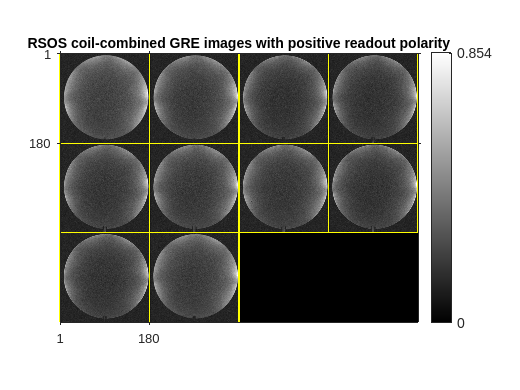

figure; im(sqrt(sum(abs(toppe.utils.ift3(ksp_gre_plus)).^2,4)),'cbar');
title('RSOS coil-combined GRE images with positive readout polarity');

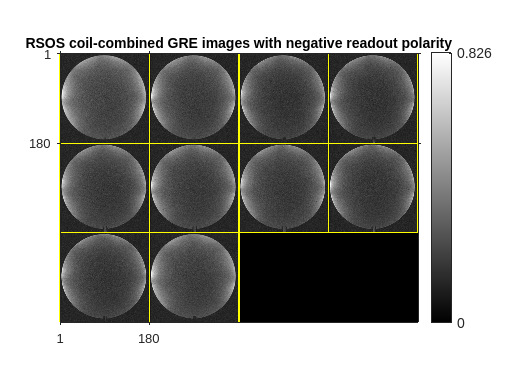

figure; im(sqrt(sum(abs(toppe.utils.ift3(ksp_gre_minus)).^2,4)),'cbar');
title('RSOS coil-combined GRE images with negative readout polarity');

## Sort apart the ACS data into + and - polarities

% Average + and - polarity frames across time
ksp_acs_plus = squeeze(mean(ksp_acs(:,:,:,:,1:2:end,:),5));
ksp_acs_minus = squeeze(mean(ksp_acs(:,:,:,:,2:2:end,:),5));

% Stack both polarities into one tensor for convenience
ksp_acs = [reshape(ksp_acs_plus,[1 size(ksp_acs_plus)]);...
           reshape(ksp_acs_minus,[1 size(ksp_acs_minus)])];

## Visualize

% Swap every other line
tmp = ksp_acs_minus(:,2:2:end,:,:,:);
ksp_acs_minus(:,2:2:end,:,:,:) = ksp_acs_plus(:,2:2:end,:,:,:);
ksp_acs_plus(:,2:2:end,:,:,:) = tmp;
clear tmp;

% Sort segments/shots into proper locations
ksp_acs_plus_sorted = zeros(Nfid,Ny,Nz,Ncoils);
ksp_acs_minus_sorted = zeros(Nfid,Ny,Nz,Ncoils);
for seg = 1:Nsegments
    ksp_acs_plus_sorted(:,seg:Nsegments:end,:,:,:) = squeeze(ksp_acs_plus(:,:,seg,:,:,:));
    ksp_acs_minus_sorted(:,seg:Nsegments:end,:,:,:) = squeeze(ksp_acs_minus(:,:,seg,:,:,:));
end

Unable to perform assignment because the size of the left side is 232-by-30-by-10-by-32 and the size of the right side is 232-by-45-by-10-by-32.


% Look at the corresponding RSOS images
figure;
im(sqrt(sum(abs(toppe.utils.ift3(ksp_acs_plus_sorted)).^2,4)),'cbar')
title('+ polarity image');
figure;
im(sqrt(sum(abs(toppe.utils.ift3(ksp_acs_minus_sorted)).^2,4)),'cbar')
title('- polarity image');

## Estimate linear phase offset of ACS data

Estimated offset from center of k-space (samples): 1.348299


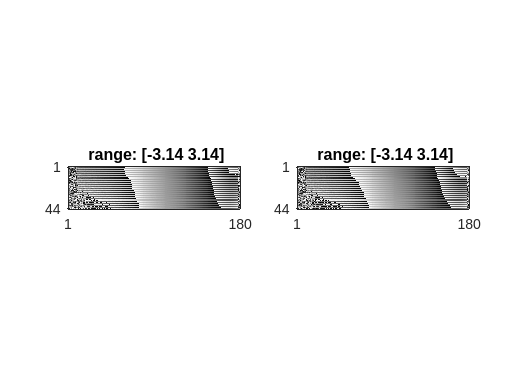

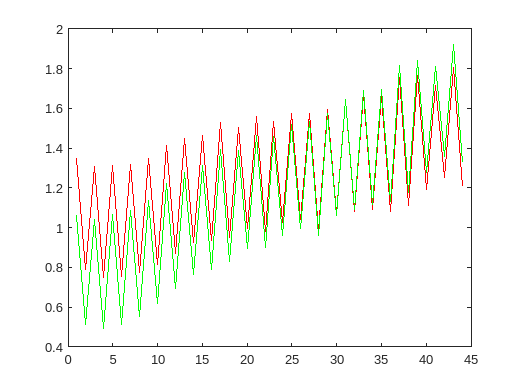

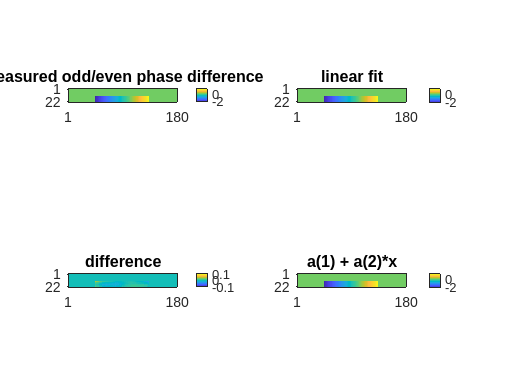

Constant phase offset (radians): -0.517990


Linear term (radians/fov): 7.303883


Estimated offset from center of k-space (samples): 0.881146


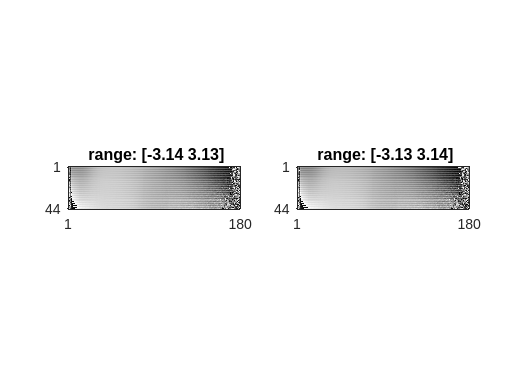

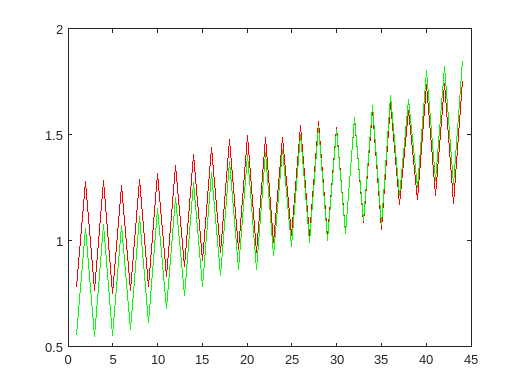

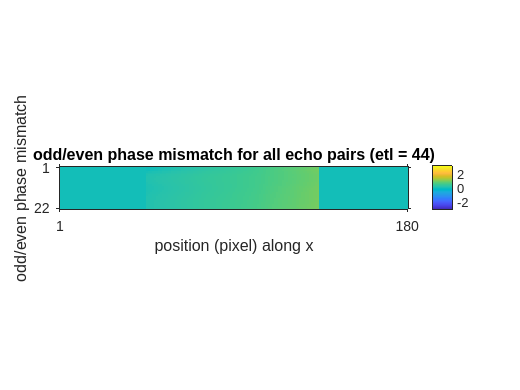

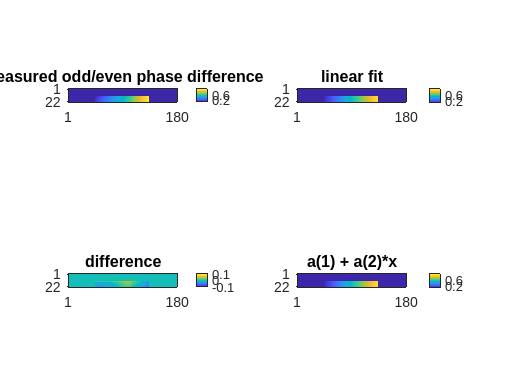

Constant phase offset (radians): 0.521845


Linear term (radians/fov): 1.656436


% Stack both polarities into one tensor for convenience
ksp_cal = [reshape(ksp_cal_plus,[1 size(ksp_cal_plus)]);...
                  reshape(ksp_cal_minus,[1 size(ksp_cal_minus)])];

kxo_locs = zeros(2,Nfid);
kxe_locs = zeros(2,Nfid);
phase_coeffs = zeros(2,2);

for polarity = 1:2 % 1 = positive, 2 = negative
    % Estimate k-space center offset due to gradient delay
    cal_data = reshape(abs(squeeze(ksp_cal(polarity,:,:,:,:,:))),Nfid,Ny/Nsegments,Nsegments*Nz*Ncoils);
    cal_data(:,2:2:end,:) = flip(cal_data(:,2:2:end,:),1); % every other line is flipped in EPI
    [M, I] = max(cal_data,[],1);
    delay = 2*mean(I,'all') - Nfid;
    fprintf('Estimated offset from center of k-space (samples): %f\n', delay);
    
    % retrieve sample locations from .mod file with adc info
    [rf,gx,gy,gz,desc,paramsint16,pramsfloat,hdr] = toppe.readmod(fn_adc);
    [kxo, kxe] = toppe.utils.getk(sysGE, fn_adc, Nfid, delay);
    kxo_locs(polarity,:) = kxo;
    kxe_locs(polarity,:) = kxe;

    % Extract even number of lines (in case ETL is odd)
    ETL_even = size(ksp_cal,3) - mod(size(ksp_cal,3),2);
    oephase_data = reshape(squeeze(ksp_cal(polarity,:,1:ETL_even,:,:,:)),...
                           Nfid, ETL_even, Nsegments*Nz*Ncoils);
    
    % EPI ghost correction phase offset values
    oephase_data = hmriutils.epi.rampsampepi2cart(oephase_data, kxo, kxe, Nx, fov(1)*100, 'nufft');
    oephase_data = ifftshift(ifft(fftshift(oephase_data),Nx,1));
    [a, th] = hmriutils.epi.getoephase(oephase_data,showEPIphaseDiff);
    fprintf('Constant phase offset (radians): %f\n', a(1));
    fprintf('Linear term (radians/fov): %f\n', a(2));

    phase_coeffs(:,polarity) = a;
end

## Apply linear phase correction to ACS data

ksp_acs_gridded = zeros(2,Nx,Ny/Nsegments,Nsegments,Nz,Ncoils);
ksp_acs_corrected = zeros(2,Nx,Ny/Nsegments,Nsegments,Nz,Ncoils);

for polarity = 1:2 % 1 = positive, 2 = negative
    kxo = kxo_locs(polarity,:);
    kxe = kxe_locs(polarity,:);

    % grid data
    tmp = hmriutils.epi.rampsampepi2cart(squeeze(ksp_acs(polarity,:,:,:,:,:)),...
                                          kxo, kxe, Nx, fov(1)*100, 'nufft');
    ksp_acs_gridded(polarity,:,:,:,:,:) = tmp;

    % phase correct
    ksp_acs_corrected(polarity,:,:,:,:,:) = hmriutils.epi.epiphasecorrect(tmp,phase_coeffs(:,polarity));
end

## Allocate segments into proper locations

ksp_acs_source = zeros(2,Nx,Ny,Nz,Ncoils);
ksp_acs_target = zeros(2,Nx,Ny,Nz,Ncoils);

for seg = 1:Nsegments
    ksp_acs_source(:,:,seg:Nsegments:end,:,:) = squeeze(ksp_acs_gridded(:,:,:,seg,:,:));
    ksp_acs_target(:,:,seg:Nsegments:end,:,:) = squeeze(ksp_acs_corrected(:,:,:,seg,:,:));
end

## Visualize

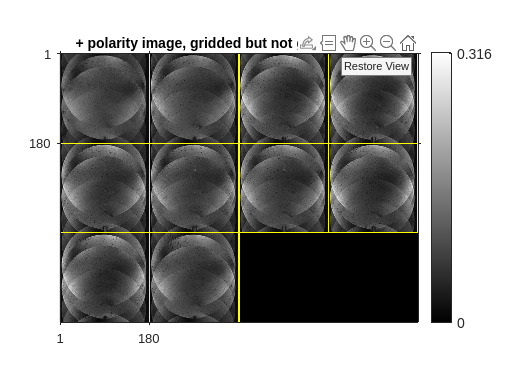

% Look at the corresponding RSOS images
figure;
im(sqrt(sum(abs(toppe.utils.ift3(squeeze(ksp_acs_source(1,:,:,:,:)))).^2,4)),'cbar')
title('+ polarity image, gridded but not ghost corrected');

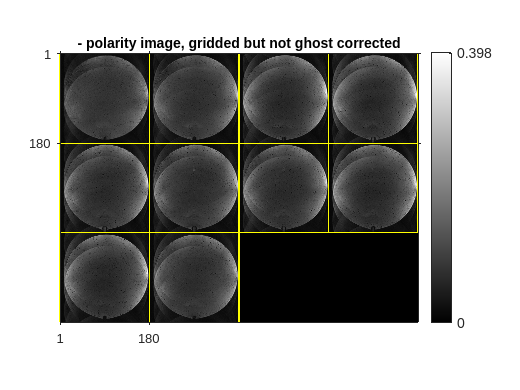

figure;
im(sqrt(sum(abs(toppe.utils.ift3(squeeze(ksp_acs_source(2,:,:,:,:)))).^2,4)),'cbar')
title('- polarity image, gridded but not ghost corrected');

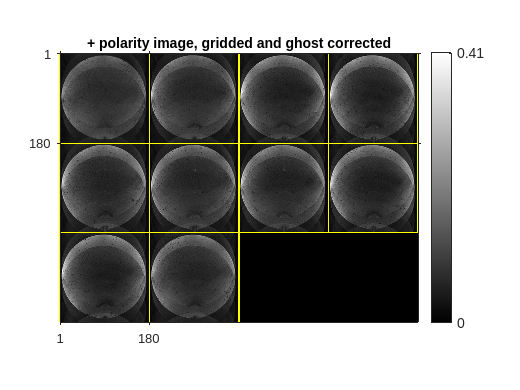


figure;
im(sqrt(sum(abs(toppe.utils.ift3(squeeze(ksp_acs_target(1,:,:,:,:)))).^2,4)),'cbar')
title('+ polarity image, gridded and ghost corrected');

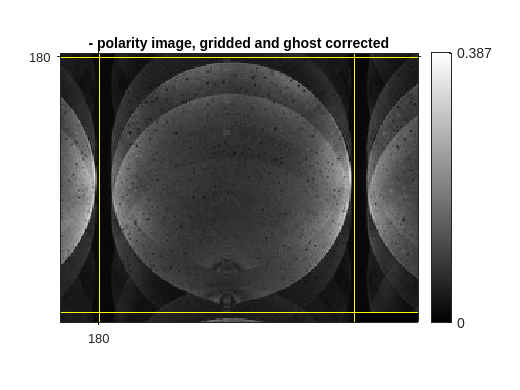

figure;
im(sqrt(sum(abs(toppe.utils.ift3(squeeze(ksp_acs_target(2,:,:,:,:)))).^2,4)),'cbar')
title('- polarity image, gridded and ghost corrected');

## Compute DPG kernel weights

## Reconstruct k-space

## Enforce low-rankness

## Display